# **NGPCA: Clustering high-dimensional and non-stationary data streams Please cite this code using the following DOI: **[**https://doi.org/10.1016/j.patcog.2023.110030**](https://doi.org/10.1016/j.patcog.2023.110030)

clear variables
close all
addpath('ngpca', 'data');
% Reproducability
rng(0)

## Create the NGPCA object

Parameters - Not case sensitive Name - Range - Default - Description 

- "potentialFunction" - "AR", "N", "H", "VRV", "AV", "VRR" - "AR" - Defines the potential function used during the ranking process 

- "softhard" - [0,1] - 0 - 0 = Softclustering more accurate but slower, 1 = Hardclustering 

- "learningrate" - [0,0.99] - 0.99 - Defines the initial learning rate for all units 

- "activity" - [0,1] - 1 - Defines the initial activity for all units 

- "rho_init" - [0,1] - 0.99 - Defines the initial neighborhood range 

- "rho_final" - [0,1] - 0.02 - Defines the final neighborhood range. Has to be smaller than rho_init 

- "mu" - [0,1] - 0.005 - Low pass filter "rmax" - [0,inf] - 200 - Defines the strength of the adaptive term in the potential function. No effect in "N" and "H" 

- Additional description of the potentialFunction abbreviations "AR" - (suggested) Potential function with an adjustable radius according to "N" - Classical Mahalanobis Distance according to "H" - Volume normalized potential function according to "VRV"- Potential function with a variable volume according to "AV" - Potential function with an adjustable volume according to "VRR"- Potential function with a variable radius according to Example object creation that overwrites the default softclustering to hardclustering

ngpca = NGPCA('softhard', 1);

## Load data - The provided .mat files contain:

The example data set (S1) is taken from [https://cs.joensuu.fi/sipu/datasets/](https://cs.joensuu.fi/sipu/datasets/) Cite the database as: P. Fänti and S. Sieranoja, K-means properties on six clustering benchmark datasets, Applied Intelligence, 48 (12), 4743-4759, December 2018 [https://doi.org/10.1007/s10489-018-1238-7](https://doi.org/10.1007/s10489-018-1238-7) 

Name - Description 

- Filename - Filename containing the data 

- Data - Training data 

- gt - Ground truth cluster centers used for CI 

- Eigenvectors and Eigenvalues used for CI 

- label - Data point labels used for NMI and DU

load('s1.mat','data','gt','label','eigenvalues','eigenvectors');

## Train on single data point

Train and visualize an NGPCA model in 3 steps in a custom loop 

- Init units: Mandatory parameters data - matrix where each row contains a n-dimensional data point - used for initializing the unit centers numberUnits - Defines the number of units --- Optional parameters "iterations" - Defines the number of iterations "PCADimensionality" - Sets the dimensionality for all units; 

- fit_single: Parameters data - training data 

- draw:

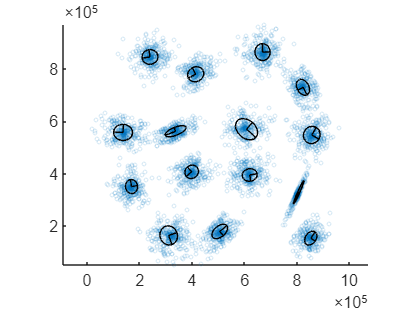

figure;
scatter(data(:,1), data(:,2),5,'o','MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
hold on;
axis equal;
axis manual;
ngpca = init_units(ngpca, data, 15, 'iterations', 20000, 'PCADimensionality', 2);
for i = 1:ngpca.iterations
    % Sample a random data point in each iteration
    ngpca = fit_single(ngpca, data(ceil(size(data,1) .* rand), :));
    % Needed to overwrite the ngpca object if plotted in a loop to delete
    % units from previous plot
    if mod(i,200) == 0
        ngpca = ngpca.draw();
    end
end

ngpca = validation(ngpca, 'gt', gt, 'eigenvalues', eigenvalues, 'eigenvectors', eigenvectors, 'label', label, 'data', data);

## Train on full data set

For parameter description see above example for single data point training.

ngpca = NGPCA();
ngpca = init_units(ngpca, data, 15, 'Iterations', 20000, 'PCADimensionality', 2);
tic;
ngpca = fit_multiple(ngpca, data);
toc

## Visualization

figure;
scatter(data(:,1), data(:,2),5,'o','MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
hold on;
ngpca.draw();

## Validation

ngpca = validation(ngpca, 'gt', gt, 'eigenvalues', eigenvalues, 'eigenvectors', eigenvectors, 'label', label, 'data', data);